# Experiment 8.1

## Name: Emily Corson and Seth Brodzik

## Objectives

To verify the effect of open-loop poles and zeros upon the shape of the root locus. To verify the root locus as a tool for estimating the effect of open-loop gain upon the transient response of closed-loop systems.    

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*Sketch two possibilities for the root locus of a unity negative-feedback system with the open-loop pole-zero configuration shown in Figure P8.21*

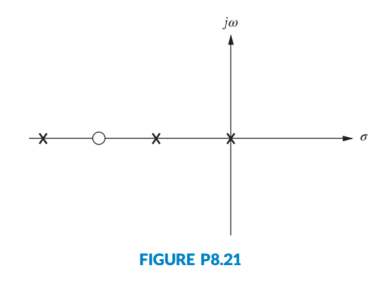

**Answer:**

One possibility for the root locus is seen below with a zero at s = -2 and poles at s = 0, -1, and -7.

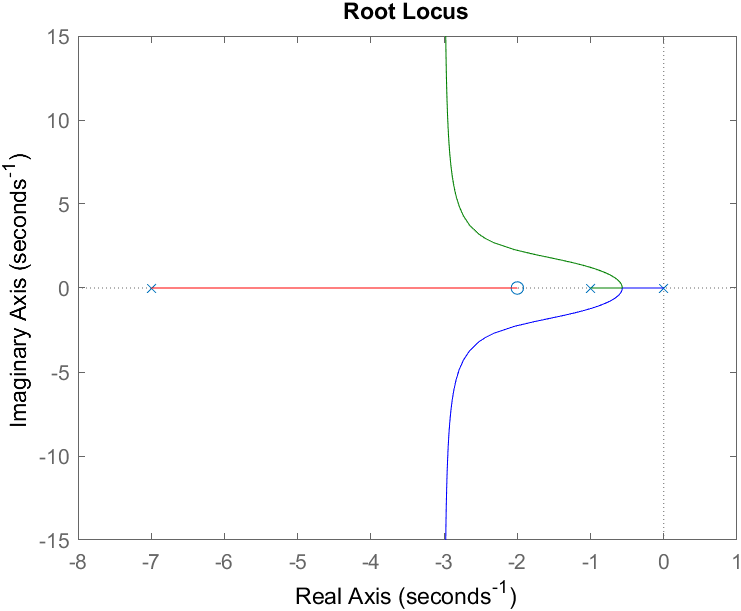

A second possibilty for the root locus is seen below with a zero at s = -2 and poles at s = 0, -1 and -3.

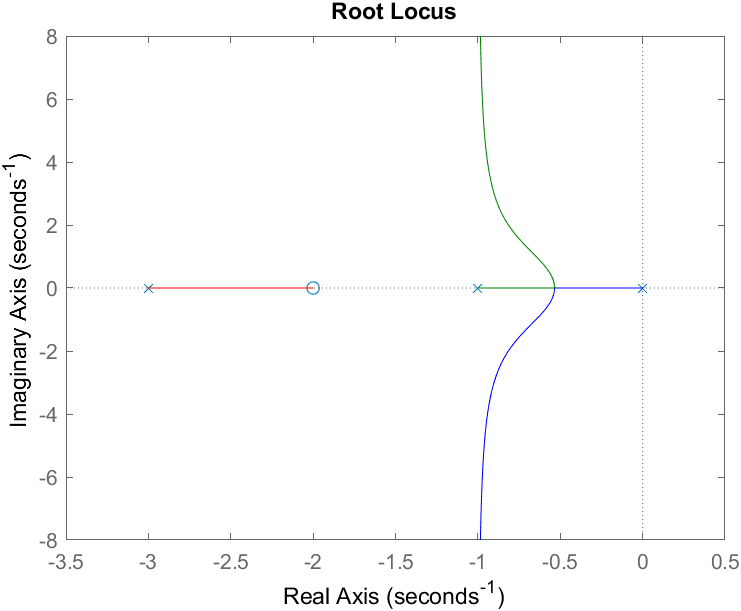

### Problem 2

*If the open-loop system of Prelab 1 is *$G(s) = \frac{K(s+1.5)}{s(s+0.5)(s+10)}$, estimate the precent overshoot at the following values of gain, $K: 20, 50, 85, 200, 700$.

**Answer:**

K = 20

g = tf([1, 1.5],[1,10.5,5,0]);
h20 = feedback(20*g, 1);
stepinfo(h20).Overshoot

ans = 18.4064

K = 50

h50 = feedback(50*g, 1);
stepinfo(h50).Overshoot

ans = 20.3710

K = 85

h85 = feedback(85*g, 1);
stepinfo(h85).Overshoot

ans = 25.9262

K = 200

h200 = feedback(200*g, 1);
stepinfo(h200).Overshoot

ans = 39.3819

K = 700

h700 = feedback(700*g, 1);
stepinfo(h700).Overshoot

ans = 59.7344

## Lab

### Problem 1

*Using MATLAB's SISO Design Tool, set up a negative unity feedback system with *$G(s) = \frac{K(s+6)}{s(s+0.5)(s+10)}$* to produce a root locus. For convenience, set up the zero at �6 using SISO Design Tool’s compensator function by simply dragging a zero to -�6 on the resulting root locus. Print the root locus for the zero at� -6. Move the zero to the following locations and print out a root locus at each location: -�2, -1.5, -1.37, and -1.2.  *

P1 = tf([1, 6],[1, 10.5, 5, 0]);

Case One: Zero at s = -6

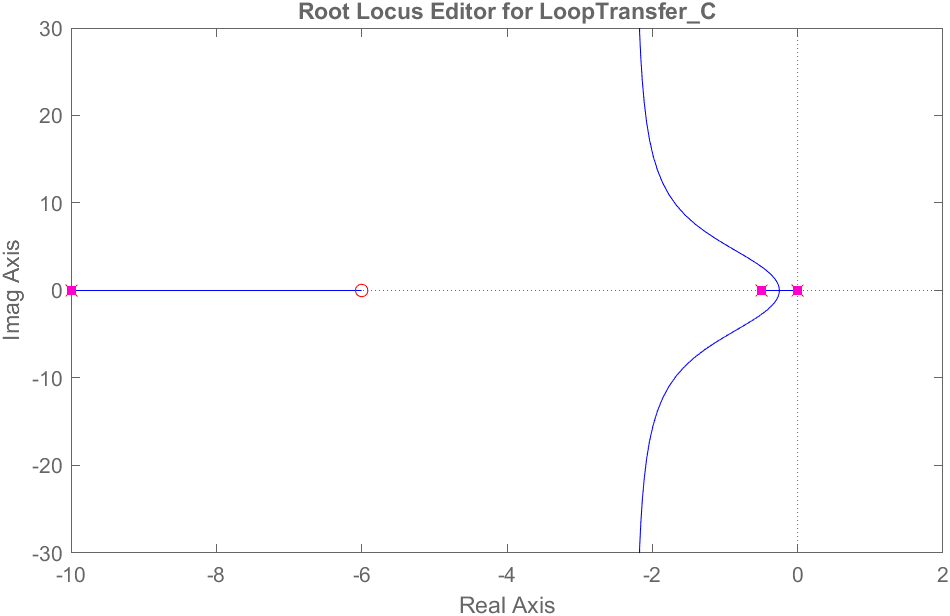

Case Two: Zero at s = -2

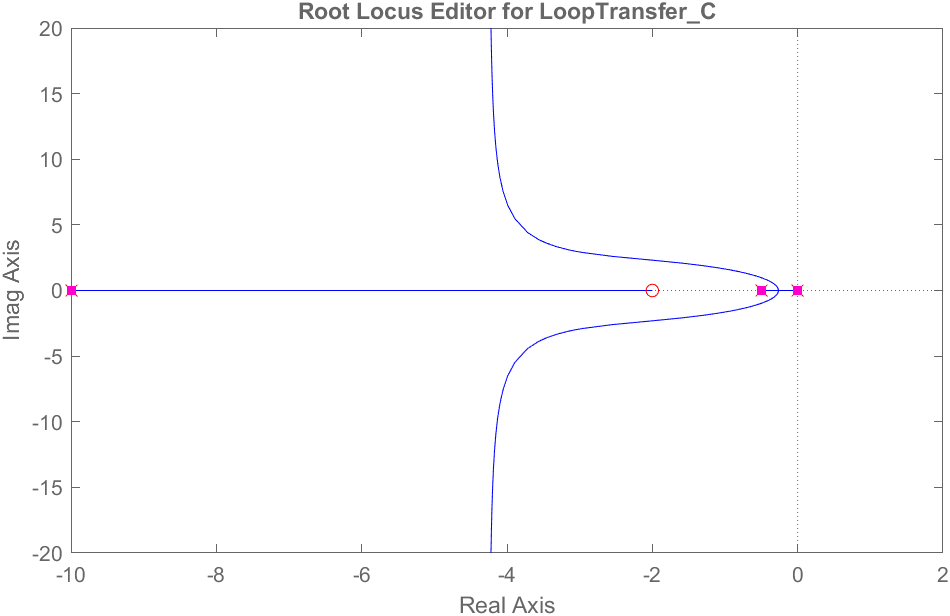

Case Three: Zero at s = -1.5

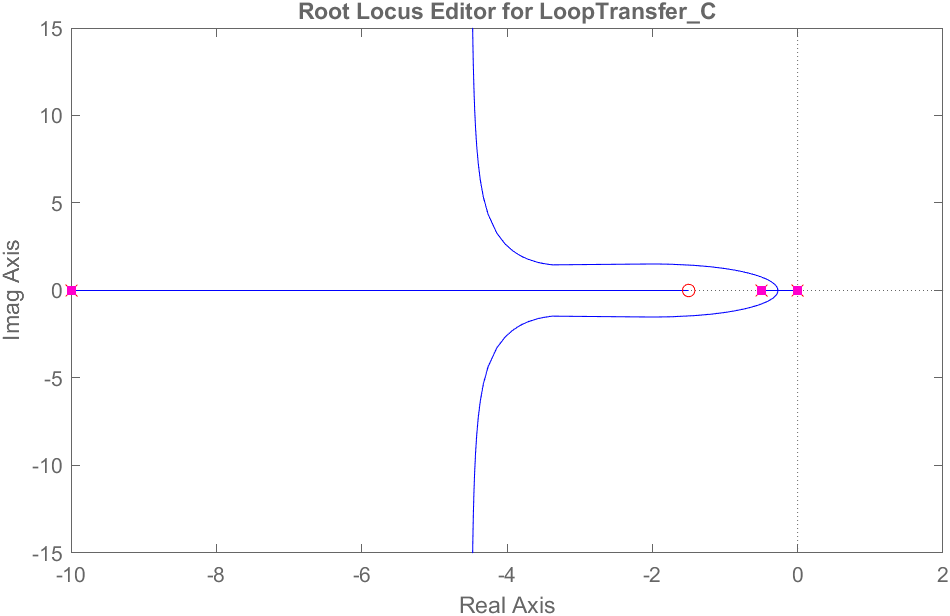

Case Four: Zero at s = -1.37

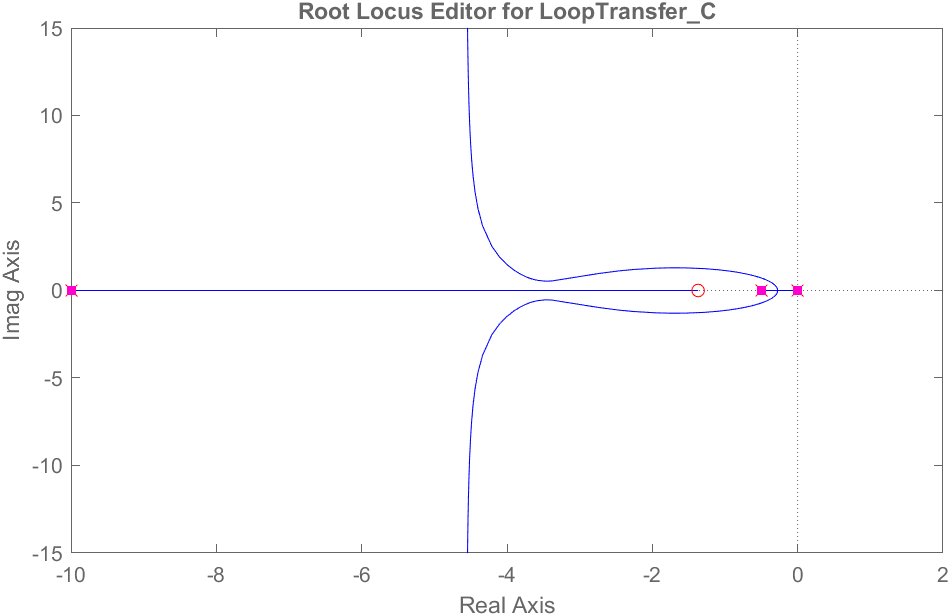

Case Five: Zero at s = -1.2

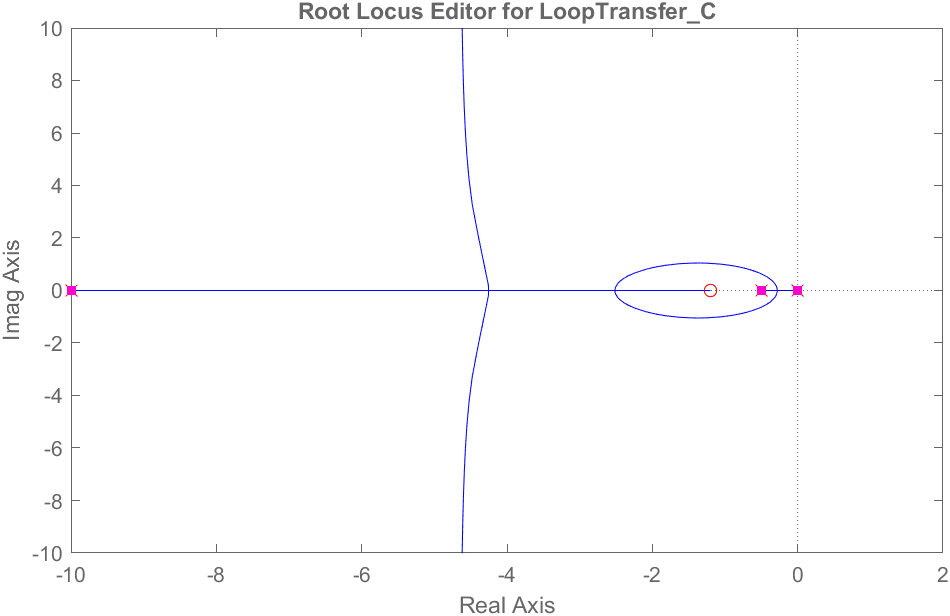

### Problem 2

*Using MATLAB's SISO Design Tool, set up a negative unity feedback system with *$G(s) = \frac{K(s+1.5)}{s(s+0.5)(s+10)}$* to produce a root locus. Open the LTI Viewer for SISO Design Tool to show step responses. Using the values of K specified in Prelab 2, record the percent overshoot and settling time and print the root loci and step response for each value of K.*

K = 20;
g = tf([1, 1.5],[1,10.5,5,0]);

K = 20, Percent Overshoot = 18.4%, Settling Time = 2.64 seconds

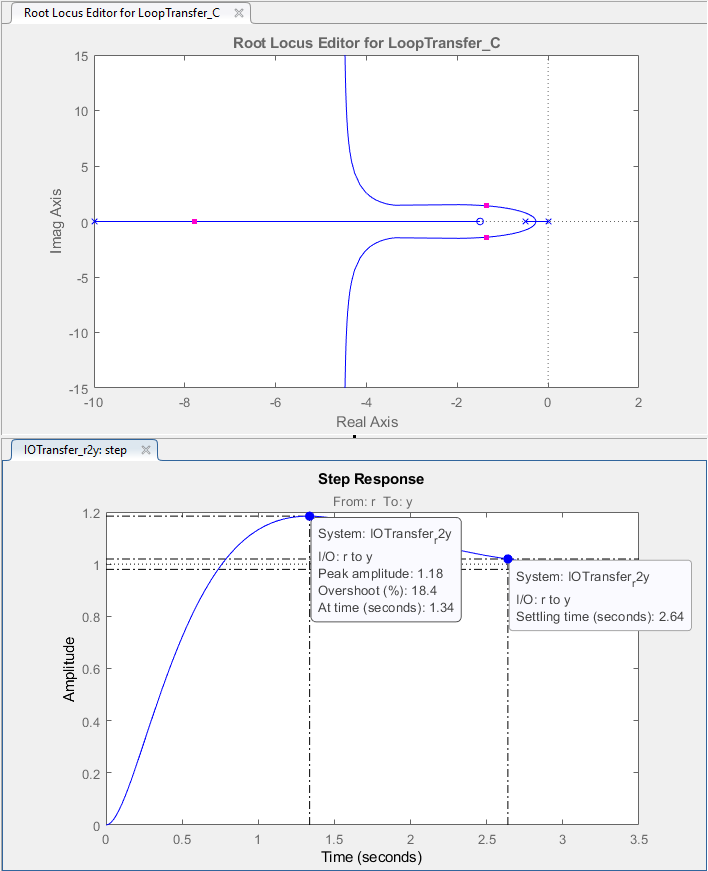

K = 50, Percent Overshoot = 20.4%, Settling Time = 1.54 seconds

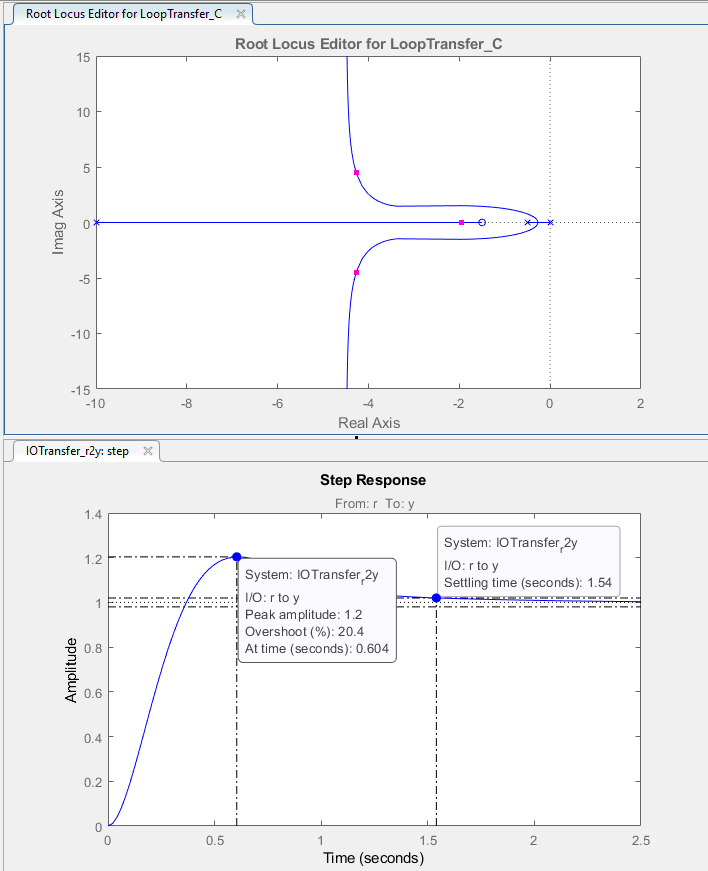

K = 85, Percent Overshoot = 25.9%, Settling Time = 1.34 seconds

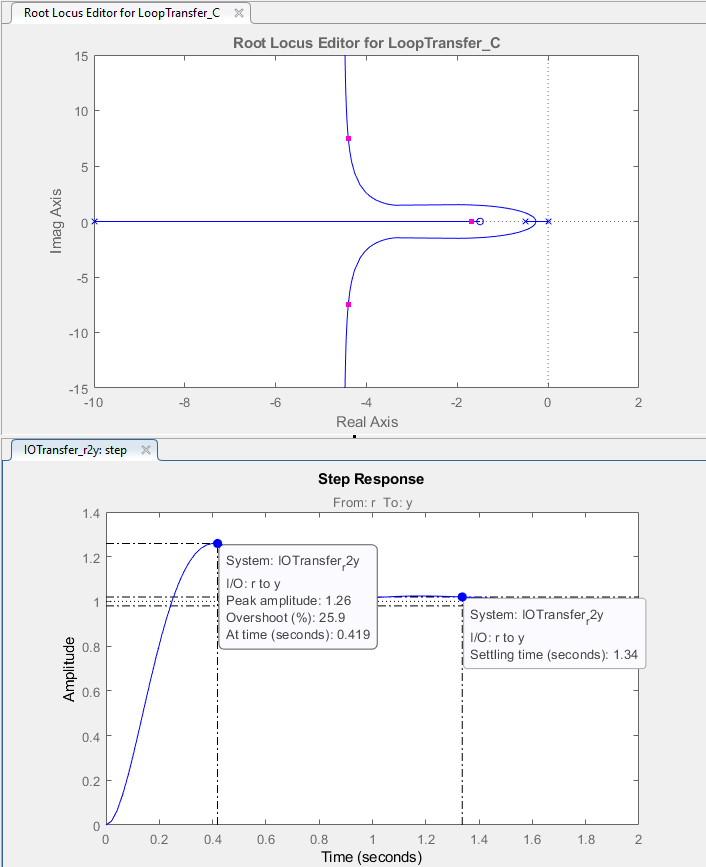

K = 200, Percent Overshoot = 39.4%, Settling Time = 0.845

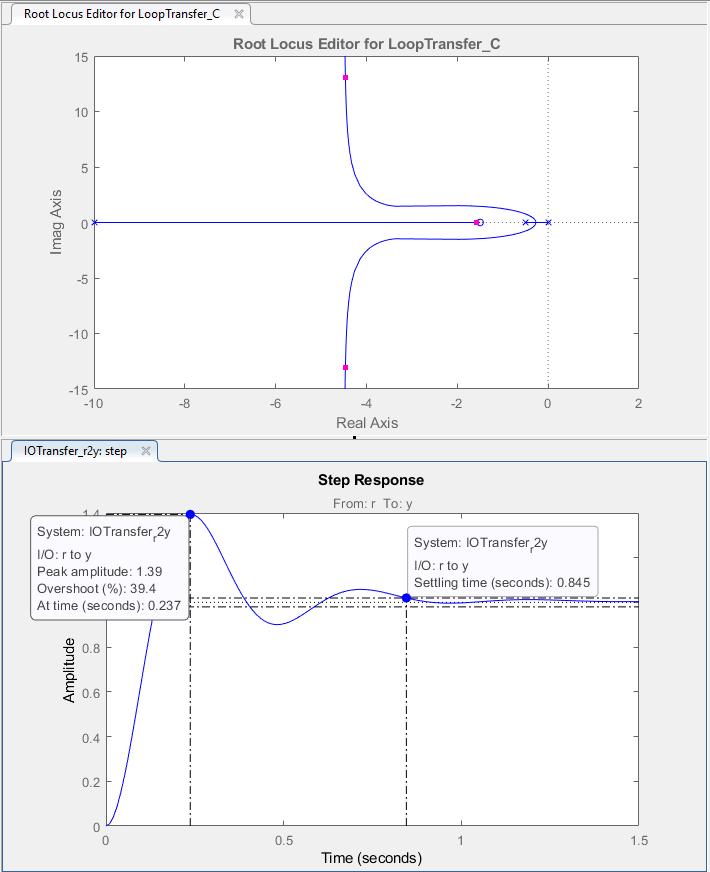

K = 700, Percent Overshoot = 59.7%, Settling Time = 0.878 seconds

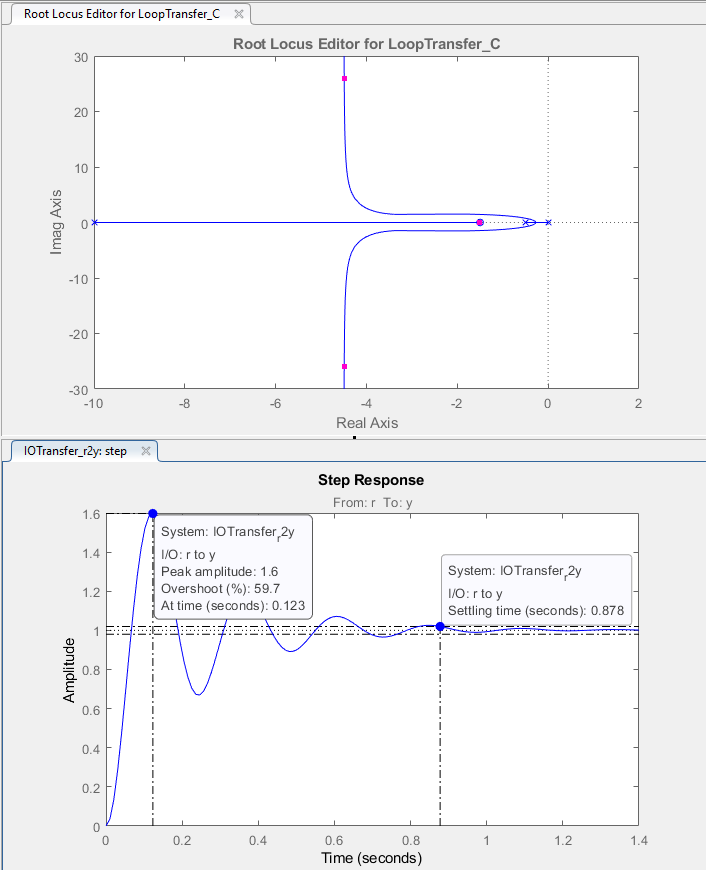

## Postlab

### Problem 1

*Discuss your findings from Prelab 1 and Lab 1. What conclusions can you draw?*

In Prelab 1, we were asked to sketch root locus possibilities given three poles and one zero. Only one of the poles had a definite location associated with it while the other poles and zero had no defined location. Since they had no defined location, there is more than one possibilty for the root locus. In the two possibilties created in PreLab 1, only the farthest pole to the left was varied while the other three were kept the same values. The poles that stayed constant had the values of s = 0 and s = -1 while the pole that varied had the values s = -7 and s = -3. The zero was located at s = -2. As seen in the graphs from PreLab 1, changing the position of the pole affected the root locus. This can be explained by the equation for finding the asymptotes for the root locus. In the equation the sum of the zeros is subtracted from the sum of the poles, and then the difference is divided by the number of poles minus the number of zeros. The denominator will be the same in both cases, but the numerator will be different. When the changing pole is -7, the numerator will be -6. When the changing pole is -3, the numerator will be -2.

In Lab 1, a transfer function was given with three poles and one zero. All of the poles stayed the same throughout the problem while the zero changed. The poles were located at s = 0, s = -0.5, and s = -10. The locations of the zero were s = -6, s = -2, s = -1.5, s = -1.37, and s = -1.2. The root locus for each zero location was different. Just like Prelab 1, this can be explained by the equation used to find the asymptotes. Each zero location produces a different asymptote.

Prelab 1 and Lab 1 show that the positions of the poles and zeros have a major impact on the root locus. Both cases had the same amount of poles and zeros. The major difference between them was in Prelab 1 the location of the pole was changing while in Lab 1 the location of the zero was changing.

### Problem 2

*Make a table comparing percent overshoot and settling time from your calculations in Prelab 2 and your experimental values found in Lab 2. Discuss the reasons for any discrepancies. What conclustions can you draw?*

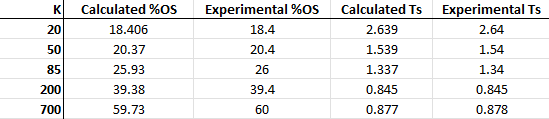

The discrepancies seen are very minimal because the same values for the damping ratio and natural frequency were used in the percent overshoot and settling time calculations. The variations in the calculated and experimental results are partially due to rounding in the calculation process.

The conclusions that can be drawn are that a higher gain (K value) leads to a larger percent overshoot, but a shorter settling time while a smaller gain leads to a smaller percent overshoot, but a longer settling time. Also, as seen in Lab 2, it is seen how the different values of gain affect the step response. The larger gains lead to more oscillations while the smaller gains lead to virtually none. Through these excerises the relationship between gain, pole and zero locations, and the step response was investigated.